% Copyright (C) <2024>, M Becker
%
% List of the contributors to the development of FLORIDyn: see LICENSE file.
% Description and complete License: see LICENSE file.
	
% This program (FLORIDyn) is free software: you can redistribute it and/or modify
% it under the terms of the GNU Affero General Public License as published by
% the Free Software Foundation, either version 3 of the License, or
% (at your option) any later version.

% This program is distributed in the hope that it will be useful,
% but WITHOUT ANY WARRANTY; without even the implied warranty of
% MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the
% GNU Affero General Public License for more details.

% You should have received a copy of the GNU Affero General Public License
% along with this program (see COPYING file).  If not, see <https://www.gnu.org/licenses/>.
% ======================================================================= %
% Updated: 16. Dez. 2024, M. Becker
% ======================================================================= %

# Limited Preview

nT          = 200;
timestep    = 5;
delta_t_phi = 20;

prev_func_lin  = linspace(1,0,nT+1);

phi = readmatrix('/Users/marcusbecker/surfdrive/PhD_Surf/01_Research/01_FLORIDyn/02_Matlab/marcusbecker@hpc06.tudelft.net/Simulations/2024_CLC/10T_HKN_00_to_03_277deg/LESData/dir.csv');
lay = readmatrix("/Users/marcusbecker/surfdrive/PhD_Surf/01_Research/01_FLORIDyn/02_Matlab/marcusbecker@hpc06.tudelft.net/Simulations/2024_CLC/10T_HKN_00_to_03_277deg/LESData/layout_balanced.csv");


distances  = sqrt((lay(:,1)-lay(:,1)').^2 + (lay(:,2)-lay(:,2)').^2);
prev_times = (round(distances(:)/(8))); %unique
prev_times(prev_times==0) = [];

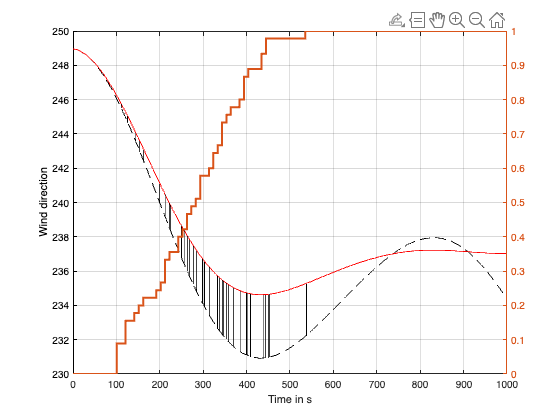

start_t = 1450;
t       = start_t:timestep:nT*timestep+start_t;%1200:timestep:phi(end,1);
phi_true = interp1(phi(:,1),phi(:,2),t);
phi_d   = [0,diff(phi_true)];
phi_pre  = phi_true(1) + cumsum(phi_d.*prev_func_lin);

figure

plot(t-start_t,phi_true,'--k','LineWidth',2)
hold on
plot(t-start_t,phi_pre,'-r','LineWidth',2)

grid on
xlabel('Time in s')
ylabel('Wind direction')

yyaxis("right")
histogram(prev_times,linspace(0,1000,100),'Normalization','cdf','DisplayStyle','stairs','LineWidth',2)
hold on
histogram(prev_times/.7,linspace(0,1000,100),'Normalization','cdf','DisplayStyle','stairs','LineWidth',2)
ylim([0,1])
xlim([0,1000])